% Read data from csv file and save to table
T = readtable('fxdata.csv', 'ReadVariableNames',false);

% Transpose the data
X = T;
Xc = table2cell(X);
X_transposed = Xc';
A = X_transposed;

% Extract currency labels and daily return value
tickers = A(1,:);
data = A(2:378,:);

% Fill missing data with previous data
data = cell2mat(data);
data = fillmissing(data, "previous",1);

% Array to store daily log-returns
size_data = size(data);
log_daily = zeros(size_data(1) - 1, size_data(2));


% Compute the daily log-returns
for j =1:size_data(2)
    for i=1:size_data(1)-1
        log_daily(i,j) = log(data(i+1,j) / data(i,j));
    end
end

% Calculate correlation matrix
correlation = corrcoef(log_daily);
distances = zeros(size_data(2), size_data(2));

% Calculate distance matrix
for j =1:size_data(2)
    for i=1:size_data(2)
        distances(i,j) = sqrt(2 * (1 - correlation(i,j)));
    end
end

% Rename the currency labels
tickers = string(tickers);
for i= 1:length(tickers)
    tickers(i) = erase(tickers(i), '/USD');
end

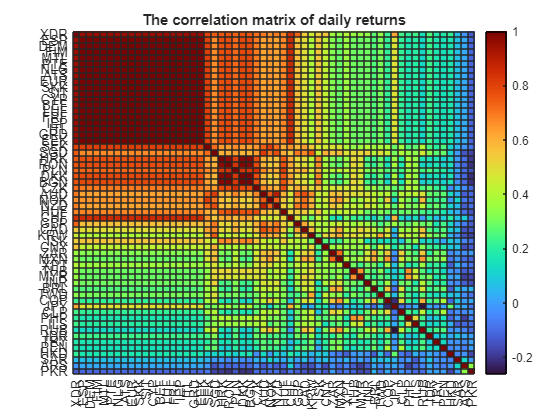

% Visualize the correlation heatmap with basic sorting algorithm
MeanCorrMatPerm=mean(correlation);
[sortedCorr, indPerm]=sort(MeanCorrMatPerm,'descend');
sorted = correlation(indPerm,indPerm);
sort_title= tickers(:,indPerm );

figure;
h = heatmap(sorted,"Colormap",turbo);
h.XDisplayLabels = string(sort_title);
h.YDisplayLabels = string(sort_title);
title("The correlation matrix of daily returns");

% Output the nodes and edges data of distance matrix for MST
OutputNetwork(distances,tickers);

% Read the created node files
opts = detectImportOptions('country-currency-region.csv');
T_country = readtable('country-currency-region.csv',opts);
country = string(T_country.Country);
region = string(T_country.Region);
node_table = readtable("nodes.csv");

% Add country and region data to each node
node_table.Country = country;
node_table.Region = region;

% Output the node table
writetable(node_table,'nodes.csv','Delimiter',';');


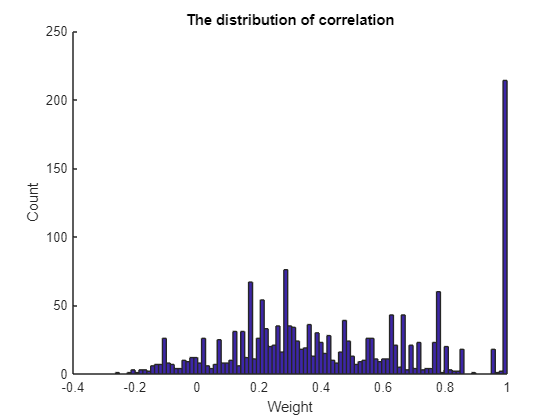

% Plot the distribution of correlation
[V, D] = eig(correlation);
eig_values = diag(D);
figure;
hold on;
title("The distribution of correlation");
xlabel("Weight");
ylabel("Count");
temp = tril(correlation);
temp = temp(temp ~= 0);
hist(temp, 100)
hold off;

% Apply Marchenko–Pastur distribution
lamda = 58/377;
lamda_plus = (1+sqrt(lamda))^2;
lamda_minus = (1-sqrt(lamda))^2;

%Calculate eigevalue/vectors for the correlation data
correlation(1:1+size(correlation,1):end) = 1;
[V1, D1] = eig(correlation);
D1_abs = abs(D1);

% Set the eigenvalues that are  indistinguishable from noise to 0
D1_filter = (D1_abs >= lamda_plus); 
D1_reconstitued = D1 .* D1_filter;

%  A*V = V*D.
correlation_reconstituted = V1 * D1_reconstitued * inv(V1);
correlation_reconstituted = abs(correlation_reconstituted);

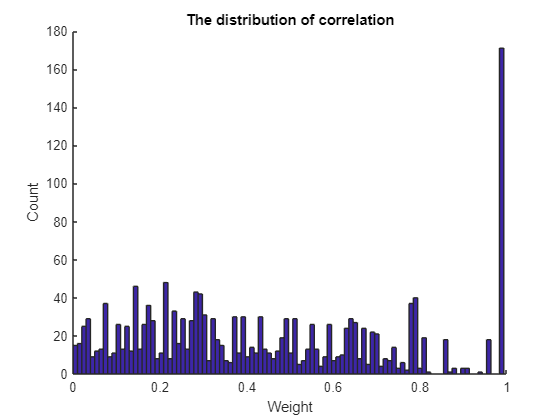

% Plot the distribution of reconstituted correlation
figure;
hold on;
title("The distribution of correlation");
xlabel("Weight");
ylabel("Count");
temp = tril(correlation_reconstituted);
temp = temp(temp ~= 0);
hist(temp, 100)
hold off;

% Output the nodes and edges data of reconstituted correlation matrix for
% currency network
OutputNetwork(correlation_reconstituted,tickers);

% Open country, region, and node data file
opts = detectImportOptions('country-currency-region.csv');
T_country = readtable('country-currency-region.csv',opts);
country = string(T_country.Country);
region = string(T_country.Region);
node_table = readtable("nodes.csv");

% Add region, country data to node table
node_table.Country = country;
node_table.Region = region;


% Output the node table
writetable(node_table,'nodes.csv','Delimiter',';');